# Examine Well-Trained Session using Temporal Field Bayes Marginals - Temporal Coding

fileDirs = [{'D:\WorkBigDataFiles\PFC\GE11_Session132'},...
    {'D:\WorkBigDataFiles\PFC\GE13_Session083'},...
    {'D:\WorkBigDataFiles\PFC\GE14_Session123'},...
    {'D:\WorkBigDataFiles\PFC\GE17_Session095'},...
    {'D:\WorkBigDataFiles\PFC\GE24_Session096'}];

binSize = 200;
dsRate = 50;
trlWindow = {[-800 2000]};
alignment = {'PokeIn'};
% trlWindow = {[-2000 800]};
% alignment = {'PokeOut'};
bayesType = 1; 
%bayseTypes: 1 = Poisson: use with raw spike counts; 2 = Bernoulli: use with binarized spike counts; 3 = Gaussian: Use with z-scored spike counts

numChancePerms = 10;

postCLim = [0 0.05];

cMap = load('roma.mat'); % flip
cMap = cMap.(cell2mat(fieldnames(cMap)));
cMap = flipud(cMap);
cMapNanW = cMap;
cMapNanW(1,:) = ones(1,3);

 %#ok<*UNRCH> 

## Compile Data

tic;
for ani = 1:length(fileDirs)
    mlb = MLB_SM(fileDirs{ani});
    % Create Analysis Variables
    if ani == 1 
        % Behavior Variables
        fiscPokeOutLat = cell(length(fileDirs),1);
        fiscRwdDelivLat = cell(length(fileDirs),1);
        % Posteriors
        realPost = cell(mlb.seqLength, 1, length(fileDirs));
        chancePost_Pos = cell(mlb.seqLength, numChancePerms, length(fileDirs));
        chancePost_Time = cell(mlb.seqLength, numChancePerms, length(fileDirs));
        chancePost_Full = cell(mlb.seqLength, numChancePerms, length(fileDirs));
    end
    mlb.binSize = binSize;
    mlb.dsRate = dsRate;
    mlb.windows = trlWindow;
    mlb.alignments = alignment;
    mlb.bayesType = bayesType;
    
    fiscPokeOutLat{ani} = ([mlb.trialInfo(mlb.fiscTrials(~isnan(mlb.fiscTrials))).PokeOutIndex] - [mlb.trialInfo(mlb.fiscTrials(~isnan(mlb.fiscTrials))).PokeInIndex])'/1000;
    fiscRwdDelivLat{ani} = ([mlb.trialInfo(mlb.fiscTrials(~isnan(mlb.fiscTrials))).RewardIndex] - [mlb.trialInfo(mlb.fiscTrials(~isnan(mlb.fiscTrials))).PokeInIndex])'/1000;
    
    % Process Observations - FISC via Leave-1-Out
    mlb.SetLikes_FISC;
    mlb.Process_Observes;
    tempPosts = mlb.OrganizeDataCellMatrix(mlb.post,3,[mlb.trialInfo(mlb.postTrlIDs).Odor],[mlb.trialInfo(mlb.postTrlIDs).Position]);
    realPost(:,1,ani) = tempPosts(logical(eye(mlb.seqLength)));
    %% Process Chance
    fprintf('.... processing chance.... ');
    for perm = 1:numChancePerms 
        mlb.Process_Observes('Full');
        tempPosts = mlb.OrganizeDataCellMatrix(mlb.post,3,[mlb.trialInfo(mlb.postTrlIDs).Odor],[mlb.trialInfo(mlb.postTrlIDs).Position]);
        chancePost_Full(:,perm,ani) = tempPosts(logical(eye(mlb.seqLength)));
        mlb.Process_Observes('Trial');
        tempPosts = mlb.OrganizeDataCellMatrix(mlb.post,3,[mlb.trialInfo(mlb.postTrlIDs).Odor],[mlb.trialInfo(mlb.postTrlIDs).Position]);
        chancePost_Pos(:,perm,ani) = tempPosts(logical(eye(mlb.seqLength)));
        mlb.Process_Observes('Time');
        tempPosts = mlb.OrganizeDataCellMatrix(mlb.post,3,[mlb.trialInfo(mlb.postTrlIDs).Odor],[mlb.trialInfo(mlb.postTrlIDs).Position]);
        chancePost_Time(:,perm,ani) = tempPosts(logical(eye(mlb.seqLength)));
    end
    fprintf('.......................... Complete\n');
end

Compiling StatMatrix Data....Completed


.... processing chance.... 

.......................... Complete


Compiling StatMatrix Data....Completed


.... processing chance.... 

.......................... Complete


Compiling StatMatrix Data....Completed


.... processing chance.... 

.......................... Complete


Compiling StatMatrix Data....Completed


.... processing chance.... 

.......................... Complete


Compiling StatMatrix Data....Completed


.... processing chance.... 

.......................... Complete


pokeOutLats = cell2mat(fiscPokeOutLat(:));
nearestPOtime = mlb.obsvTimeVect(find(mlb.obsvTimeVect<median(pokeOutLats),1,'last'));
rwdDelivLat = cell2mat(fiscRwdDelivLat(:));
nearestRWDtime = mlb.obsvTimeVect(find(mlb.obsvTimeVect<median(rwdDelivLat),1,'last'));
piNdx = find(mlb.likeTimeVect==0)+0.5;
poNdx = find(mlb.likeTimeVect==nearestPOtime)+0.5;
rwdNdx = find(mlb.likeTimeVect==nearestRWDtime)+0.5;
posNdx = find(diff(mlb.likeTimeVect)<0)+0.5;
toc

Elapsed time is 449.445434 seconds.


## Collapse Trials Across Animals

tic;
%TIP = Time-In-Position
groupPostTIP_Real = cell(mlb.seqLength,1);
groupPostTime_Real = cell(mlb.seqLength,1);
groupPostPos_Real = cell(mlb.seqLength,1);

groupPostTIP_FullChance = cell(mlb.seqLength,1);
groupPostTime_FullChance = cell(mlb.seqLength,1);
groupPostPos_FullChance = cell(mlb.seqLength,1);

groupPostTIP_PosChance = cell(mlb.seqLength,1);
groupPostTime_PosChance = cell(mlb.seqLength,1);
groupPostPos_PosChance = cell(mlb.seqLength,1);

groupPostTIP_TimeChance = cell(mlb.seqLength,1);
groupPostTime_TimeChance = cell(mlb.seqLength,1);
groupPostPos_TimeChance = cell(mlb.seqLength,1);

for pos = 1:mlb.seqLength
    % Temporal Field PDF
    groupPostTIP_Real{pos} = cell2mat(realPost(pos,:,:));
    % Marginal Time PDF
    groupPostTime_Real{pos} = mlb.TabulateBayesPost(groupPostTIP_Real{pos}, mlb.decodeIDvects(:,1));
    % Marginal Position PDF
    groupPostPos_Real{pos} = mlb.TabulateBayesPost(groupPostTIP_Real{pos}, mlb.decodeIDvects(:,3));
    % Chance - Create temporary variables to reorganize & combine chance data
    % Full Chance
    tempPostTIP_FullChance = nan(length(mlb.obsvTimeVect), length(mlb.likeTimeVect), numChancePerms);
    tempPostTime_FullChance = nan(length(mlb.obsvTimeVect), length(mlb.obsvTimeVect), numChancePerms);
    tempPostPos_FullChance = nan(length(mlb.obsvTimeVect), mlb.seqLength, numChancePerms);
    % Position Chance
    tempPostTIP_PosChance = nan(length(mlb.obsvTimeVect), length(mlb.likeTimeVect), numChancePerms);
    tempPostTime_PosChance = nan(length(mlb.obsvTimeVect), length(mlb.obsvTimeVect), numChancePerms);
    tempPostPos_PosChance = nan(length(mlb.obsvTimeVect), mlb.seqLength, numChancePerms);
    % Time Chance
    tempPostTIP_TimeChance = nan(length(mlb.obsvTimeVect), length(mlb.likeTimeVect), numChancePerms);
    tempPostTime_TimeChance = nan(length(mlb.obsvTimeVect), length(mlb.obsvTimeVect), numChancePerms);
    tempPostPos_TimeChance = nan(length(mlb.obsvTimeVect), mlb.seqLength, numChancePerms);
    parfor perm = 1:numChancePerms
        % Full Chance
        curChanceFull = cell2mat(chancePost_Full(pos,perm,:));
        tempPostTIP_FullChance(:,:,perm) = mean(curChanceFull,3);
        tempPostTime_FullChance(:,:,perm) = mean(mlb.TabulateBayesPost(curChanceFull, mlb.decodeIDvects(:,1)),3, 'omitnan'); %#ok<PFBNS> 
        tempPostPos_FullChance(:,:,perm) = mean(mlb.TabulateBayesPost(curChanceFull, mlb.decodeIDvects(:,3)),3, 'omitnan');
        % Position Chance
        curChancePos = cell2mat(chancePost_Pos(pos,perm,:));
        tempPostTIP_PosChance(:,:,perm) = mean(curChancePos,3);
        tempPostTime_PosChance(:,:,perm) = mean(mlb.TabulateBayesPost(curChancePos, mlb.decodeIDvects(:,1)),3, 'omitnan');
        tempPostPos_PosChance(:,:,perm) = mean(mlb.TabulateBayesPost(curChancePos, mlb.decodeIDvects(:,3)),3, 'omitnan');
        % Time Chance
        curChanceTime = cell2mat(chancePost_Time(pos,perm,:));
        tempPostTIP_TimeChance(:,:,perm) = mean(curChanceTime,3);
        tempPostTime_TimeChance(:,:,perm) = mean(mlb.TabulateBayesPost(curChanceTime, mlb.decodeIDvects(:,1)),3, 'omitnan');
        tempPostPos_TimeChance(:,:,perm) = mean(mlb.TabulateBayesPost(curChanceTime, mlb.decodeIDvects(:,3)),3, 'omitnan');
    end
    % Full Chance
    groupPostTIP_FullChance{pos} = mean(tempPostTIP_FullChance, 3,'omitnan');
    groupPostTime_FullChance{pos} = mean(tempPostTime_FullChance, 3, 'omitnan');
    groupPostPos_FullChance{pos} = mean(tempPostPos_FullChance, 3, 'omitnan');
    % Position Chance
    groupPostTIP_PosChance{pos} = mean(tempPostTIP_PosChance, 3,'omitnan');
    groupPostTime_PosChance{pos} = mean(tempPostTime_PosChance, 3, 'omitnan');
    groupPostPos_PosChance{pos} = mean(tempPostPos_PosChance, 3, 'omitnan');
    % Time Chance
    groupPostTIP_TimeChance{pos} = mean(tempPostTIP_TimeChance, 3,'omitnan');
    groupPostTime_TimeChance{pos} = mean(tempPostTime_TimeChance, 3, 'omitnan');
    groupPostPos_TimeChance{pos} = mean(tempPostPos_TimeChance, 3, 'omitnan');
end
numSeqs = size(groupPostTIP_Real{1},3);
toc

Elapsed time is 61.139040 seconds.


## Plot Marginal Temporal Probabilities by Position - Full Chance

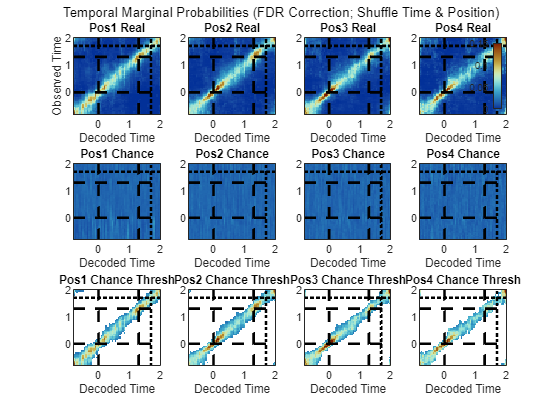

figure;
sps = nan(3,mlb.seqLength);
for pos = 1:mlb.seqLength
    tempObsvProbs = mean(groupPostTime_Real{pos},3,'omitnan');
    sps(pos,1) = subplot(3, mlb.seqLength, sub2ind([mlb.seqLength,3], pos,1));
    imagesc(mlb.obsvTimeVect, mlb.obsvTimeVect, tempObsvProbs, [0 0.15]);
    set(gca, 'ydir', 'normal');
    colormap(sps(pos,1),cMap);
    title(sprintf('Pos%i Real', pos));
    xlabel('Decoded Time');
    hold on;
    plot(zeros(1,2), get(gca, 'ylim'), '--k', 'linewidth', 2);
    plot(get(gca, 'xlim'), zeros(1,2), '--k', 'linewidth', 2);
    plot(repmat(nearestPOtime, [1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    plot(get(gca, 'xlim'), repmat(nearestPOtime, [1,2]), '--k', 'linewidth', 2);
    plot(repmat(nearestRWDtime, [1,2]), get(gca, 'ylim'), ':k', 'linewidth', 2);
    plot(get(gca, 'xlim'), repmat(nearestRWDtime, [1,2]), ':k', 'linewidth', 2);

    sps(pos,2) = subplot(3, mlb.seqLength, sub2ind([mlb.seqLength,3], pos,2));
    imagesc(mlb.obsvTimeVect, mlb.obsvTimeVect, groupPostTime_FullChance{pos,1}, [0 0.15]);
    set(gca, 'ydir', 'normal');
    colormap(sps(pos,2),cMap);
    title(sprintf('Pos%i Chance', pos));
    xlabel('Decoded Time');
    hold on;
    plot(zeros(1,2), get(gca, 'ylim'), '--k', 'linewidth', 2);
    plot(get(gca, 'xlim'), zeros(1,2), '--k', 'linewidth', 2);
    plot(repmat(nearestPOtime, [1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    plot(get(gca, 'xlim'), repmat(nearestPOtime, [1,2]), '--k', 'linewidth', 2);
    plot(repmat(nearestRWDtime, [1,2]), get(gca, 'ylim'), ':k', 'linewidth', 2);
    plot(get(gca, 'xlim'), repmat(nearestRWDtime, [1,2]), ':k', 'linewidth', 2);

    sigVal = nan(size(tempObsvProbs));
    for t1 = 1:length(mlb.obsvTimeVect)
        for t2 = 1:length(mlb.obsvTimeVect)
            [~,sigVal(t1,t2)] = ttest(groupPostTime_Real{pos}(t1,t2,:), groupPostTime_FullChance{pos,1}(t1,t2), 'Tail', 'Right');
        end
    end
%     sigLog = sigVal<0.05;
    [~,q] = mafdr(sigVal(:));
    sigLog = reshape(q,size(sigVal))<0.05;
    tempObsvProbs(~sigLog) = nan;
    tempObsvProbs(tempObsvProbs==0) = 1e-100;
    sps(pos,3) = subplot(3, mlb.seqLength, sub2ind([mlb.seqLength,3],pos,3));
    imagesc(mlb.obsvTimeVect, mlb.obsvTimeVect, tempObsvProbs, [0 0.15]);
    set(gca, 'ydir', 'normal');
    colormap(sps(pos,3),cMapNanW);
    title(sprintf('Pos%i Chance Thresh', pos));
    xlabel('Decoded Time');
    hold on;
    plot(zeros(1,2), get(gca, 'ylim'), '--k', 'linewidth', 2);
    plot(get(gca, 'xlim'), zeros(1,2), '--k', 'linewidth', 2);
    plot(repmat(nearestPOtime, [1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    plot(get(gca, 'xlim'), repmat(nearestPOtime, [1,2]), '--k', 'linewidth', 2);
    plot(repmat(nearestRWDtime, [1,2]), get(gca, 'ylim'), ':k', 'linewidth', 2);
    plot(get(gca, 'xlim'), repmat(nearestRWDtime, [1,2]), ':k', 'linewidth', 2);
end
annotation(gcf,'textbox', [0.1 0.95 0.9 0.05],...
        'String', 'Temporal Marginal Probabilities (FDR Correction; Shuffle Time & Position)',...
        'FontSize',10, 'edgecolor', 'none', 'horizontalalignment', 'left');
ylabel(sps(1), 'Observed Time');
colorbar(sps(mlb.seqLength,1), 'location', 'east');

## Plot Marginal Temporal Probabilities by Position - Position Chance

figure;
sps = nan(3,mlb.seqLength);
for pos = 1:mlb.seqLength
    tempObsvProbs = mean(groupPostTime_Real{pos},3,'omitnan');
    sps(pos,1) = subplot(3, mlb.seqLength, sub2ind([mlb.seqLength,3], pos,1));
    imagesc(mlb.obsvTimeVect, mlb.obsvTimeVect, tempObsvProbs, [0 0.15]);
    set(gca, 'ydir', 'normal');
    colormap(sps(pos,1),cMap);
    title(sprintf('Pos%i Real', pos));
    xlabel('Decoded Time');
    hold on;
    plot(zeros(1,2), get(gca, 'ylim'), '--k', 'linewidth', 2);
    plot(get(gca, 'xlim'), zeros(1,2), '--k', 'linewidth', 2);
    plot(repmat(nearestPOtime, [1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    plot(get(gca, 'xlim'), repmat(nearestPOtime, [1,2]), '--k', 'linewidth', 2);
    plot(repmat(nearestRWDtime, [1,2]), get(gca, 'ylim'), ':k', 'linewidth', 2);
    plot(get(gca, 'xlim'), repmat(nearestRWDtime, [1,2]), ':k', 'linewidth', 2);

    sps(pos,2) = subplot(3, mlb.seqLength, sub2ind([mlb.seqLength,3], pos,2));
    imagesc(mlb.obsvTimeVect, mlb.obsvTimeVect, groupPostTime_PosChance{pos,1}, [0 0.15]);
    set(gca, 'ydir', 'normal');
    colormap(sps(pos,2),cMap);
    title(sprintf('Pos%i Chance', pos));
    xlabel('Decoded Time');
    hold on;
    plot(zeros(1,2), get(gca, 'ylim'), '--k', 'linewidth', 2);
    plot(get(gca, 'xlim'), zeros(1,2), '--k', 'linewidth', 2);
    plot(repmat(nearestPOtime, [1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    plot(get(gca, 'xlim'), repmat(nearestPOtime, [1,2]), '--k', 'linewidth', 2);
    plot(repmat(nearestRWDtime, [1,2]), get(gca, 'ylim'), ':k', 'linewidth', 2);
    plot(get(gca, 'xlim'), repmat(nearestRWDtime, [1,2]), ':k', 'linewidth', 2);

    sigVal = nan(size(tempObsvProbs));
    for t1 = 1:length(mlb.obsvTimeVect)
        for t2 = 1:length(mlb.obsvTimeVect)
            [~,sigVal(t1,t2)] = ttest(groupPostTime_Real{pos}(t1,t2,:), groupPostTime_PosChance{pos,1}(t1,t2), 'Tail', 'Right');
        end
    end
%     sigLog = sigVal<0.05;
    [~,q] = mafdr(sigVal(:));
    sigLog = reshape(q,size(sigVal))<0.05;
    tempObsvProbs(~sigLog) = nan;
    tempObsvProbs(tempObsvProbs==0) = 1e-100;
    sps(pos,3) = subplot(3, mlb.seqLength, sub2ind([mlb.seqLength,3],pos,3));
    imagesc(mlb.obsvTimeVect, mlb.obsvTimeVect, tempObsvProbs, [0 0.15]);
    set(gca, 'ydir', 'normal');
    colormap(sps(pos,3),cMapNanW);
    title(sprintf('Pos%i Chance Thresh', pos));
    xlabel('Decoded Time');
    hold on;
    plot(zeros(1,2), get(gca, 'ylim'), '--k', 'linewidth', 2);
    plot(get(gca, 'xlim'), zeros(1,2), '--k', 'linewidth', 2);
    plot(repmat(nearestPOtime, [1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    plot(get(gca, 'xlim'), repmat(nearestPOtime, [1,2]), '--k', 'linewidth', 2);
    plot(repmat(nearestRWDtime, [1,2]), get(gca, 'ylim'), ':k', 'linewidth', 2);
    plot(get(gca, 'xlim'), repmat(nearestRWDtime, [1,2]), ':k', 'linewidth', 2);
end

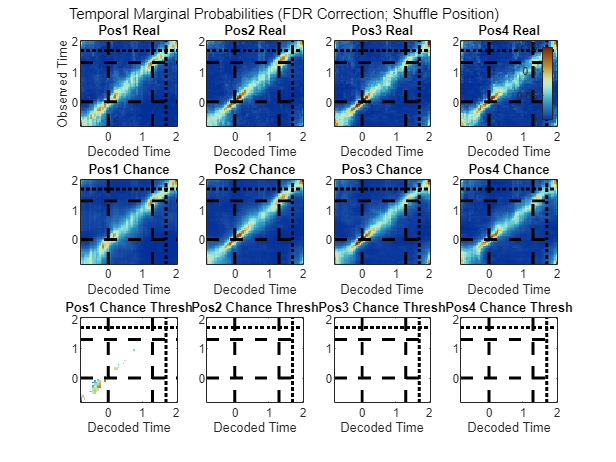

annotation(gcf,'textbox', [0.1 0.95 0.9 0.05],...
        'String', 'Temporal Marginal Probabilities (FDR Correction; Shuffle Position)',...
        'FontSize',10, 'edgecolor', 'none', 'horizontalalignment', 'left');
ylabel(sps(1), 'Observed Time');
colorbar(sps(mlb.seqLength,1), 'location', 'east');

## Plot Marginal Temporal Probabilities by Position - Time Chance

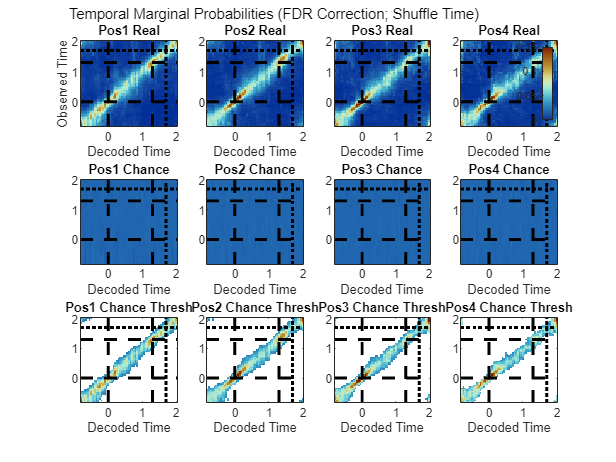

figure;
sps = nan(3,mlb.seqLength);
for pos = 1:mlb.seqLength
    tempObsvProbs = mean(groupPostTime_Real{pos},3,'omitnan');
    sps(pos,1) = subplot(3, mlb.seqLength, sub2ind([mlb.seqLength,3], pos,1));
    imagesc(mlb.obsvTimeVect, mlb.obsvTimeVect, tempObsvProbs, [0 0.15]);
    set(gca, 'ydir', 'normal');
    colormap(sps(pos,1),cMap);
    title(sprintf('Pos%i Real', pos));
    xlabel('Decoded Time');
    hold on;
    plot(zeros(1,2), get(gca, 'ylim'), '--k', 'linewidth', 2);
    plot(get(gca, 'xlim'), zeros(1,2), '--k', 'linewidth', 2);
    plot(repmat(nearestPOtime, [1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    plot(get(gca, 'xlim'), repmat(nearestPOtime, [1,2]), '--k', 'linewidth', 2);
    plot(repmat(nearestRWDtime, [1,2]), get(gca, 'ylim'), ':k', 'linewidth', 2);
    plot(get(gca, 'xlim'), repmat(nearestRWDtime, [1,2]), ':k', 'linewidth', 2);

    sps(pos,2) = subplot(3, mlb.seqLength, sub2ind([mlb.seqLength,3], pos,2));
    imagesc(mlb.obsvTimeVect, mlb.obsvTimeVect, groupPostTime_TimeChance{pos,1}, [0 0.15]);
    set(gca, 'ydir', 'normal');
    colormap(sps(pos,2),cMap);
    title(sprintf('Pos%i Chance', pos));
    xlabel('Decoded Time');
    hold on;
    plot(zeros(1,2), get(gca, 'ylim'), '--k', 'linewidth', 2);
    plot(get(gca, 'xlim'), zeros(1,2), '--k', 'linewidth', 2);
    plot(repmat(nearestPOtime, [1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    plot(get(gca, 'xlim'), repmat(nearestPOtime, [1,2]), '--k', 'linewidth', 2);
    plot(repmat(nearestRWDtime, [1,2]), get(gca, 'ylim'), ':k', 'linewidth', 2);
    plot(get(gca, 'xlim'), repmat(nearestRWDtime, [1,2]), ':k', 'linewidth', 2);

    sigVal = nan(size(tempObsvProbs));
    for t1 = 1:length(mlb.obsvTimeVect)
        for t2 = 1:length(mlb.obsvTimeVect)
            [~,sigVal(t1,t2)] = ttest(groupPostTime_Real{pos}(t1,t2,:), groupPostTime_TimeChance{pos,1}(t1,t2), 'Tail', 'Right');
        end
    end
%     sigLog = sigVal<0.05;
    [~,q] = mafdr(sigVal(:));
    sigLog = reshape(q,size(sigVal))<0.05;
    tempObsvProbs(~sigLog) = nan;
    tempObsvProbs(tempObsvProbs==0) = 1e-100;
    sps(pos,3) = subplot(3, mlb.seqLength, sub2ind([mlb.seqLength,3],pos,3));
    imagesc(mlb.obsvTimeVect, mlb.obsvTimeVect, tempObsvProbs, [0 0.15]);
    set(gca, 'ydir', 'normal');
    colormap(sps(pos,3),cMapNanW);
    title(sprintf('Pos%i Chance Thresh', pos));
    xlabel('Decoded Time');
    hold on;
    plot(zeros(1,2), get(gca, 'ylim'), '--k', 'linewidth', 2);
    plot(repmat(nearestPOtime, [1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    plot(repmat(nearestRWDtime, [1,2]), get(gca, 'ylim'), ':k', 'linewidth', 2);
    plot(get(gca, 'xlim'), zeros(1,2), '--k', 'linewidth', 2);
    plot(get(gca, 'xlim'), repmat(nearestPOtime, [1,2]), '--k', 'linewidth', 2);
    plot(get(gca, 'xlim'), repmat(nearestRWDtime, [1,2]), ':k', 'linewidth', 2);
end
annotation(gcf,'textbox', [0.1 0.95 0.9 0.05],...
        'String', 'Temporal Marginal Probabilities (FDR Correction; Shuffle Time)',...
        'FontSize',10, 'edgecolor', 'none', 'horizontalalignment', 'left');
ylabel(sps(1), 'Observed Time');
colorbar(sps(mlb.seqLength,1), 'location', 'east');

## Examine True-Correct Temporal Coding for Temporal Variance in Magnitudes

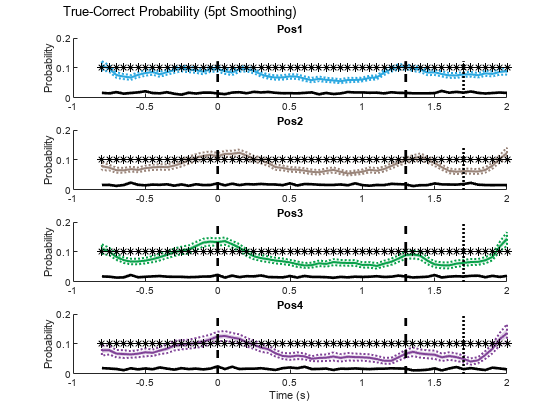

figure;
plts = nan(1,mlb.seqLength);
sps = nan(1,mlb.seqLength);
netSize = 1;
diags = cell(1,mlb.seqLength);
for pos = 1:mlb.seqLength
%     tempDiag = squeeze(reshape(groupPostTime_Real{pos}(logical(repmat(eye(length(mlb.obsvTimeVect)), [1,1,numSeqs]))), [1,length(mlb.obsvTimeVect),numSeqs]));
    tempDiag = nan(length(mlb.obsvTimeVect), size(groupPostTime_Real{pos},3));
    tempChanceDiag = groupPostTime_TimeChance{pos,1}(logical(eye(length(mlb.obsvTimeVect))));
    for s = 1:size(groupPostTime_Real{pos},3)
        tempTimeMtx = groupPostTime_Real{pos}(:,:,s);
        for t = 1:length(mlb.obsvTimeVect)
            if t == 1
                tempVals = tempTimeMtx(t:t+netSize,t:t+netSize);
            elseif t-netSize<1
                tempVals = tempTimeMtx(1:t+netSize, 1:t+netSize);
            elseif t == length(mlb.obsvTimeVect)
                tempVals = tempTimeMtx(t-netSize:t,t-netSize:t);
            elseif t+netSize>length(mlb.obsvTimeVect)
                tempVals = tempTimeMtx(t-netSize:end,t-netSize:end);
            else
                tempVals = tempTimeMtx(t-netSize:t+netSize,t-netSize:t+netSize);
            end
            tempDiag(t,s) = mean(tempVals(:));
        end
    end
    sps(pos) = subplot(mlb.seqLength,1, pos);
    plts(pos) = mlb.PlotMeanVarLine(mlb.obsvTimeVect, tempDiag, 2, 0.05, mlb.PositionColors(pos,:));
    diags{pos} = tempDiag;

    tempSigVals = nan(length(mlb.obsvTimeVect),1);
    for t = 1:length(mlb.obsvTimeVect)
        [~,tempSigVals(t)] = ttest(tempDiag(t,:), tempChanceDiag(t), 'Tail', 'Right');
    end
    tempSigVect = tempSigVals<(0.05/length(mlb.obsvTimeVect));
    tempSigVect = tempSigVect.*0.1;
    tempSigVect(tempSigVect==0) = nan;
    scatter(mlb.obsvTimeVect, tempSigVect,'*', 'k');
    
    plot(mlb.obsvTimeVect, tempChanceDiag, '-k', 'linewidth', 2);
    plot(zeros(1,2), get(gca, 'ylim'), '--k', 'linewidth', 2);
    plot(repmat(nearestPOtime, [1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    plot(repmat(nearestRWDtime, [1,2]), get(gca, 'ylim'), ':k', 'linewidth', 2);
    title(sprintf('Pos%i', pos));
    ylabel('Probability');
end
linkaxes(sps, 'xy');
xlabel('Time (s)');

annotation(gcf,'textbox', [0.1 0.95 0.9 0.05],...
        'String', sprintf('True-Correct Probability (%ipt Smoothing)', netSize*4+1),...
        'FontSize',10, 'edgecolor', 'none', 'horizontalalignment', 'left');

## True-Correct Temporal Probability Structure Correlations (Mean-Wise)

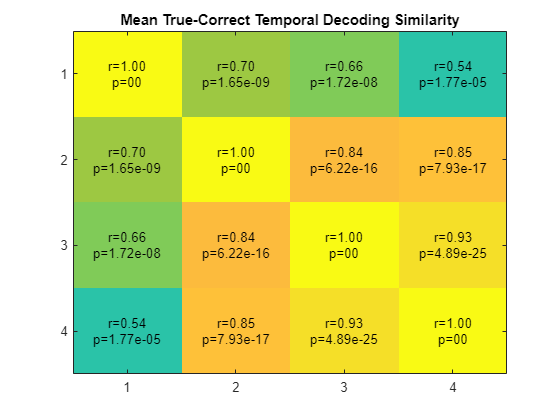

meanDiags = cell2mat(cellfun(@(a){mean(a,2)},diags));
figure;
imagesc(corr(meanDiags), [0 1]);
sigVals = nan(mlb.seqLength);
rVals = nan(mlb.seqLength);
for p1 = 1:mlb.seqLength
    for p2 = 1:mlb.seqLength
         [r,p] = corrcoef(meanDiags(:,p1), meanDiags(:,p2));
         rVals(p1,p2) = r(2);
         sigVals(p1,p2) = p(2);
         text(p2,p1, [{sprintf('r=%.02f', r(2))};{sprintf('p=%.02i', p(2))}], 'HorizontalAlignment', 'center');
    end
end
set(gca, 'xtick', 1:4, 'ytick', 1:4)
title('Mean True-Correct Temporal Decoding Similarity')

## True-Correct Temporal Probability Structure Correlations (Trial-Wise)

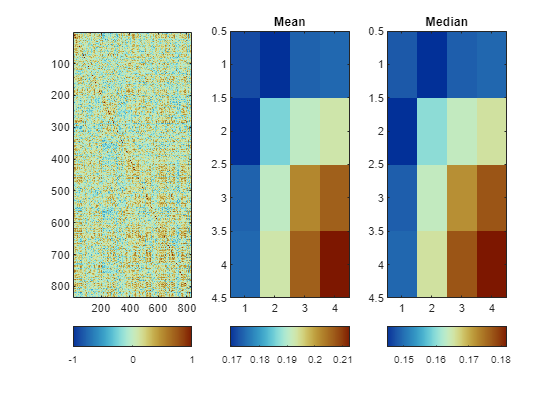

posDecodeCorr = cell(mlb.seqLength, mlb.seqLength);
for pos1 = 1:mlb.seqLength
    for pos2 = 1:mlb.seqLength
        posDecodeCorr{pos1,pos2} = corr(diags{pos1}, diags{pos2});
        if pos1==pos2
            posDecodeCorr{pos1,pos2} = posDecodeCorr{pos1,pos2}(triu(true(size(posDecodeCorr{pos1,pos2})),1));
        else
            posDecodeCorr{pos1,pos2} = posDecodeCorr{pos1,pos2}(:);
        end
    end
end
figure; 
subplot(1,3,1);
imagesc(corr(cell2mat(diags)), [-1 1]);
colorbar('southoutside');
subplot(1,3,2);
imagesc(cellfun(@(a)mean(abs(a)),posDecodeCorr));
colorbar('southoutside');
title('Mean');
subplot(1,3,3);
imagesc(cellfun(@(a)median(abs(a)),posDecodeCorr));
colorbar('southoutside');
title('Median');
colormap(cMap)